# prepare satellite mass function

## perliminaries

bp=illustris.set_env(100)

*** cosmolgy for TNG100 has been set: *** 
hub= 0.677 
Omm = 0.31 
Oml= 0.69 
Omb= 0.0486 
***  *** 
*** You are now analyzing the TNG100 Simulation. ENJOY!  *** 


bp = '\\wsl.localhost\Ubuntu-24.04\home\eladzing\sshfsMounts\vera\IllustrisTNG\simulationOutput/L75n1820TNG/output'

snap=99;
global illUnits
global cosmoStruct

[subs, fofs, subsInfo]=illustris.loadFofSub(snap);
illustris.utils.set_illUnits(snap);

fofs = illustris.utils.addTvirFofs( fofs);
M200c=double(fofs.Group_M_Crit200(subsInfo.hostFof+1)).*illUnits.massUnit;
R200c=double(fofs.Group_R_Crit200(subsInfo.hostFof+1));  %.*illUnits.lengthUnit;
T200c=double(fofs.Group_T_Crit200(subsInfo.hostFof+1));

## prepare mask s

% basic mask 
massThresh=10^9; % threshold for *stellar* mass
massAllGals=illustris.utils.get_stellar_mass(subs,'gal');
satMaskBase=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'gas','sats');

fprintf('Number of Sats: %i',sum(satMaskBase))

Number of Sats: 5080

massBins=[11.5 12.5; 12.5 13.5; 13.5 14.6];
fofM200=log10(fofs.Group_M_Crit200.*illUnits.massUnit);

for i=1:3


    % fofs mask
    fofMask=fofM200>=massBins(i,1) & fofM200<massBins(i,2);

    fprintf('Number of Fofs in mass bin %f - %f : %i',...
        massBins(i,1),massBins(i,2),sum(fofMask));


    massFunc(i).satMask=fofMask(subsInfo.hostFof+1) & satMaskBase;
    massFunc(i).stellarMass=massAllGals(massFunc(i).satMask);
    massFunc(i).gasMass=subs.SubhaloMassType(illustris.partTypeNum('gas')+1,massFunc(i).satMask).*illUnits.massUnit;
    fprintf('Number of Sats in fofs : %i',sum(massFunc(i).satMask))
end

Number of Fofs in mass bin 11.500000 - 12.500000 : 4880

Number of Sats in fofs : 1581

Number of Fofs in mass bin 12.500000 - 13.500000 : 522

Number of Sats in fofs : 2170

Number of Fofs in mass bin 13.500000 - 14.600000 : 60

Number of Sats in fofs : 1218

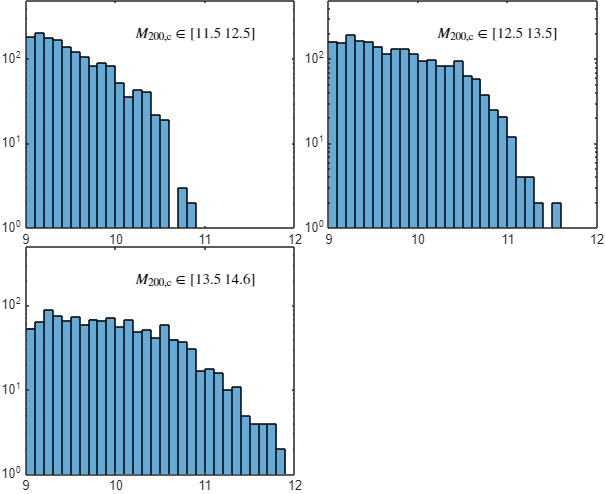

myFigure;
tt=tiledlayout(2,2,'TileSpacing','tight','Padding','tight');
for i=1:3
nexttile
histogram(log10(massFunc(i).stellarMass),9:0.1:12)
set(gca,'yscale','log')
xlim([9 12])
ylim([1 500])
tag="$M_\mathrm{200,c} \in [" + string(massBins(i,1)) + "\," +string(massBins(i,2)) +"]$";
text(10.2,200,tag,'Interpreter','latex')
end

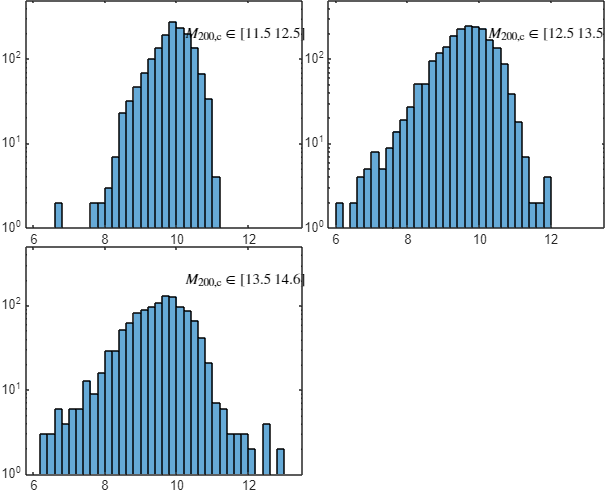


myFigure;
tt=tiledlayout(2,2,'TileSpacing','tight','Padding','tight');
for i=1:3
nexttile
histogram(log10(massFunc(i).gasMass),5.8:0.2:13.6)
set(gca,'yscale','log')
xlim([5.8 13.5])
ylim([1 500])
tag="$M_\mathrm{200,c} \in [" + string(massBins(i,1)) + "\," +string(massBins(i,2)) +"]$";
text(10.2,200,tag,'Interpreter','latex')
end